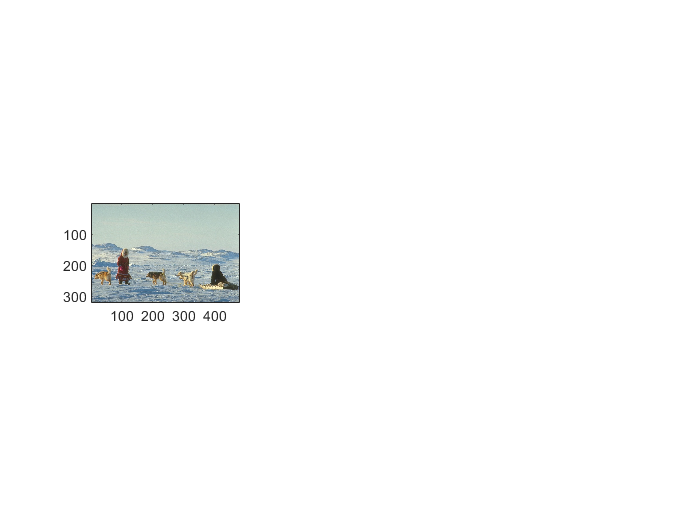

img = imread('./images/310007.jpg');
subplot(1,3,1); imagesc(img); axis image;

[X,L] = getfeatures(img, 7);
XX = [X(1:2,:); X(3:4,:)/10];

% hc=5;
% hp=6;
% h=10;
% [Y, C] = meanshift(XX, hc, hp, h);

hc1=3;
hc2=4;
hp1=8;
hp2=6;
h=10;
[Y, C] = meanshift_plus(XX, hc1, hc2, hp1, hp2, h);

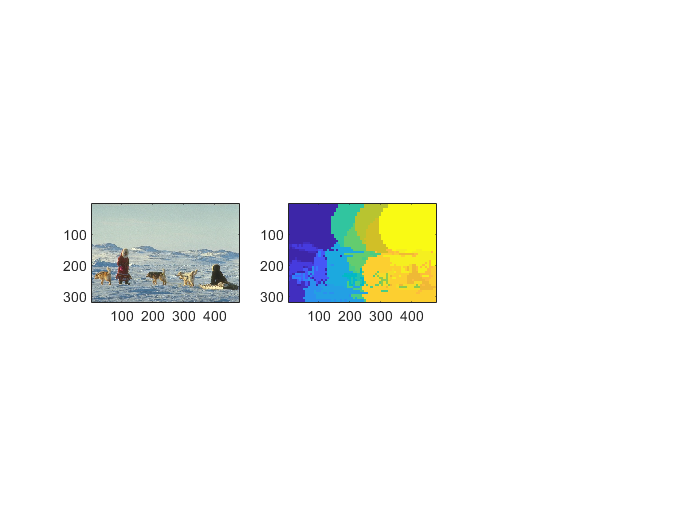

segm = labels2segm(Y,L);
subplot(1,3,2); imagesc(segm); axis image;

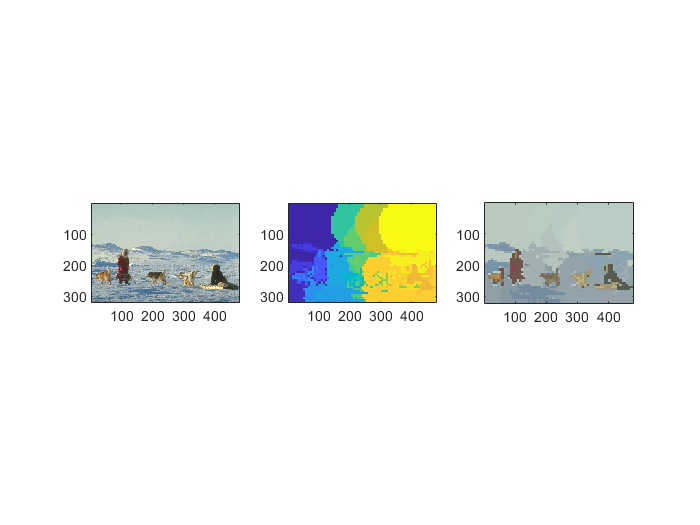

csegm = colorsegm(segm,img);
subplot(1,3,3); imagesc(csegm); axis image

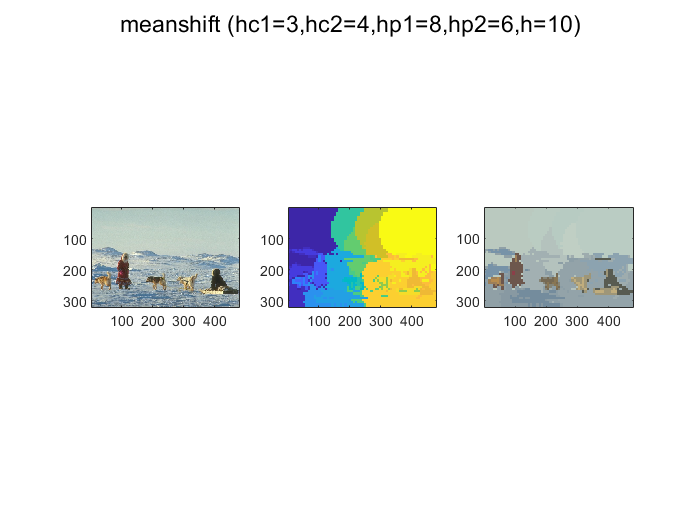

sgtitle('meanshift (hc1=3,hc2=4,hp1=8,hp2=6,h=10)');